%% Quadcopter Mission Attribute Estimator
% Cleaned version for MATLAB R2025b / Simulink workspace initialization
% F450 frame, 6S 22Ah LiPo, 50km RT + 12min loiter mission
%
% Outputs: mass, energy, endurance, TWR, feasibility table, plots
% Exports: structs to base workspace for Simulink use

clear; clc; close all;

%% 1) VEHICLE SPECIFICATION
veh.nMotors        = 4;
veh.gravity_mps2   = 9.81;
veh.frameMass_kg   = 0.55;
veh.motorMass_kg   = 0.042 * 4;
veh.escMass_kg     = 0.045  * 4;
veh.propMass_kg    = 0.013  * 4;
veh.fcGpsMass_kg   = 0.12;
veh.cameraMass_kg  = 0.03;
veh.jetsonMass_kg  = 0.14;
veh.commsMass_kg   = 0.12;
veh.wiringMass_kg  = 0.15;
veh.payloadMass_kg = 0.15;
veh.batteryMass_kg = 2.40;
veh.totalMass_kg   = sum([veh.frameMass_kg, veh.motorMass_kg, veh.escMass_kg, ...
                          veh.propMass_kg, veh.fcGpsMass_kg, veh.cameraMass_kg, ...
                          veh.jetsonMass_kg, veh.commsMass_kg, veh.wiringMass_kg, ...
                          veh.payloadMass_kg, veh.batteryMass_kg]);

%% 2) BATTERY SPECIFICATION
bat.nominalVoltage_V   = 22.2;  % 6S LiPo
bat.capacity_Ah        = 22;    % 22000mAh
bat.safeDischargeFrac  = 0.80;  % 80% depth of discharge
bat.reserveFrac        = 0.15;  % 15% mission reserve
bat.maxC               = 25;
bat.nominalEnergy_Wh   = bat.nominalVoltage_V * bat.capacity_Ah;
bat.usableEnergy_Wh    = bat.nominalEnergy_Wh * bat.safeDischargeFrac;
bat.maxCurrent_A       = bat.capacity_Ah * bat.maxC;

%% 3) PROPULSION SYSTEM
prop.thrustEach_kgf    = 2.36;  % T-Motor F90 + 10x4.5 prop
prop.totalThrust_kgf   = veh.nMotors * prop.thrustEach_kgf;
prop.totalThrust_N     = prop.totalThrust_kgf * veh.gravity_mps2;
prop.vehicleWeight_N   = veh.totalMass_kg * veh.gravity_mps2;
prop.TWR               = prop.totalThrust_N / prop.vehicleWeight_N;
prop.hoverThrottle     = veh.totalMass_kg / prop.totalThrust_kgf;

%% 4) POWER BUDGET
pwr.propCruise_W       = 280;   % Propulsion forward flight
pwr.propHover_W        = 380;   % Propulsion hover/loiter
pwr.sensors_W          = 18;    % Camera + GPS
pwr.companion_W        = 12;    % Jetson Nano
pwr.comms_W            = 10;    % ELRS + LTE
pwr.hotel_W            = pwr.sensors_W + pwr.companion_W + pwr.comms_W;
pwr.totalCruise_W      = pwr.propCruise_W + pwr.hotel_W;
pwr.totalHover_W       = pwr.propHover_W + pwr.hotel_W;

%% 5) MISSION PROFILE
mission.outbound_km    = 20;
mission.return_km      = 20;
mission.totalDistance_km = mission.outbound_km + mission.return_km;
mission.cruiseSpeed_kmh = 22 * 3.6;  % 22 m/s
mission.loiter_min     = 8;
mission.loiter_hr      = mission.loiter_min / 60;
mission.travel_hr      = mission.totalDistance_km / mission.cruiseSpeed_kmh;
mission.mission_hr     = mission.travel_hr + mission.loiter_hr;
mission.required_hr    = mission.mission_hr / (1 - bat.reserveFrac);

%% 6) ENERGY ANALYSIS
energy.travel_Wh       = pwr.totalCruise_W * mission.travel_hr;
energy.loiter_Wh       = pwr.totalHover_W * mission.loiter_hr;
energy.total_Wh        = energy.travel_Wh + energy.loiter_Wh;
energy.required_Wh     = energy.total_Wh / (1 - bat.reserveFrac);
energy.margin_Wh       = bat.usableEnergy_Wh - energy.required_Wh;

%% 7) ELECTRICAL ANALYSIS
current.cruise_A       = pwr.totalCruise_W / bat.nominalVoltage_V;
current.hover_A        = pwr.totalHover_W / bat.nominalVoltage_V;
current.average_A      = energy.total_Wh / mission.mission_hr / bat.nominalVoltage_V;

%% 8) PERFORMANCE METRICS
perf.cruiseEndurance_hr = bat.usableEnergy_Wh / pwr.totalCruise_W;
perf.hoverEndurance_hr  = bat.usableEnergy_Wh / pwr.totalHover_W;
perf.maxRange_km       = perf.cruiseEndurance_hr * mission.cruiseSpeed_kmh;
perf.reserveEndurance_hr = (bat.usableEnergy_Wh - energy.total_Wh) / pwr.totalCruise_W;

%% 9) FEASIBILITY ASSESSMENT
feasible.energyOK     = energy.margin_Wh >= 0;
feasible.currentOK    = current.cruise_A <= bat.maxCurrent_A;
feasible.twrOK        = prop.TWR >= 2.0;
feasible.overall      = feasible.energyOK && feasible.currentOK && feasible.twrOK;

%% 10) RESULTS TABLE
% Force everything to scalar double - handles structs, arrays, logicals automatically
% CORRECT - Horizontal concatenation [row1; row2; ...] WRONG
% Use this instead:
% Define ALL as column cell arrays (18x1)
metrics = {'Total Mass'; 'Usable Energy'; 'Mission Energy'; 'Energy Margin'; ...
           'Round Trip'; 'Cruise Speed'; 'Mission Time'; 'Required Time'; ...
           'Cruise Power'; 'Hover Power'; 'Cruise Current'; 'Max Current'; ...
           'Cruise Endurance'; 'Hover Endurance'; 'Max Range'; ...
           'TWR'; 'Hover Throttle'; 'Mission Feasible'};

values = [veh.totalMass_kg; bat.usableEnergy_Wh; energy.total_Wh; energy.margin_Wh; ...
          mission.totalDistance_km; mission.cruiseSpeed_kmh; mission.mission_hr; mission.required_hr; ...
          pwr.totalCruise_W; pwr.totalHover_W; current.cruise_A; bat.maxCurrent_A; ...
          perf.cruiseEndurance_hr; perf.hoverEndurance_hr; perf.maxRange_km; ...
          prop.TWR; prop.hoverThrottle; double(feasible.overall)];

units = {'kg'; 'Wh'; 'Wh'; 'Wh'; 'km'; 'km/h'; 'h'; 'h'; ...
         'W'; 'W'; 'A'; 'A'; 'h'; 'h'; 'km'; '-'; '-'; ''};

% Now table works perfectly - all are 18x1
results = table(metrics, values, units, ...
                'VariableNames', {'Metric', 'Value', 'Unit'});

fprintf('Metrics: %d rows\n', length(metrics));

Metrics: 18 rows


fprintf('Values: %d rows\n', length(values)); 

Values: 18 rows


fprintf('Units: %d rows\n', length(units));

Units: 18 rows


fprintf('\n=== QUADCOPTER MISSION RESULTS ===\n');


=== QUADCOPTER MISSION RESULTS ===


disp(results);

           Metric            Value        Unit   
    ____________________    _______    __________

    {'Total Mass'      }       4.06    {'kg'    }
    {'Usable Energy'   }     390.72    {'Wh'    }
    {'Mission Energy'  }     217.62    {'Wh'    }
    {'Energy Margin'   }      134.7    {'Wh'    }
    {'Round Trip'      }         40    {'km'    }
    {'Cruise Speed'    }       79.2    {'km/h'  }
    {'Mission Time'    }    0.63838    {'h'     }
    {'Required Time'   }    0.75104    {'h'     }
    {'Cruise Power'    }        320    {'W'     }
    {'Hover Power'     }        420    {'W'     }
    {'Cruise Current'  }     14.414    {'A'     }
    {'Max Current'     }        550    {'A'     }
    {'Cruise Endurance'}      1.221    {'h'     }
    {'Hover Endurance' }    0.93029    {'h'     }
    {'Max Range'       }     96.703    {'km'    }
    {'TWR'             }     2.3251    {'-'    

fprintf('\n=== SUMMARY ===\n');


=== SUMMARY ===


fprintf('✓ Mass: %.1f kg\n', veh.totalMass_kg);

✓ Mass: 4.1 kg


fprintf('✓ TWR: %.2f:1\n', prop.TWR);

✓ TWR: 2.33:1


fprintf('✓ Energy margin: %.1f Wh (%.1f%%)\n', energy.margin_Wh, 100*energy.margin_Wh/bat.usableEnergy_Wh);

✓ Energy margin: 134.7 Wh (34.5%)


fprintf('✓ Mission: %s\n', string(feasible.overall));

✓ Mission: true


fprintf('✓ Endurance: %.1f h cruise / %.1f h hover\n', perf.cruiseEndurance_hr, perf.hoverEndurance_hr);

✓ Endurance: 1.2 h cruise / 0.9 h hover


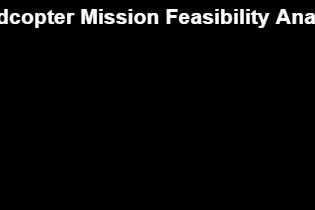


%% 11) VISUALIZATION
fig = figure('Name','Quadcopter Mission Analysis', ...
    'Color','k', ...
    'Position',[100 100 1200 800]);

t = tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
title(t,'Quadcopter Mission Feasibility Analysis', ...
    'Color','w', ...
    'FontSize',16, ...
    'FontWeight','bold');

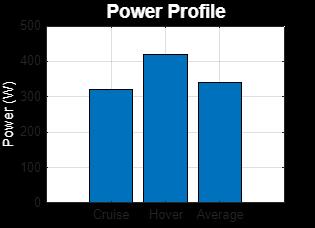


%% Tile 1: Power
%% Plot 1: Power Profile
figure('Name','Power Profile', ...
       'Color','k', ...
       'WindowStyle','normal', ...
       'Position',[100 100 900 650]);

ax = axes;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
bar([pwr.totalCruise_W pwr.totalHover_W current.average_A*bat.nominalVoltage_V], 'FaceColor','flat');
set(gca,'XTickLabel',{'Cruise','Hover','Average'});
title('Power Profile','Color','w','FontSize',14);
ylabel('Power (W)','Color','w');
grid on

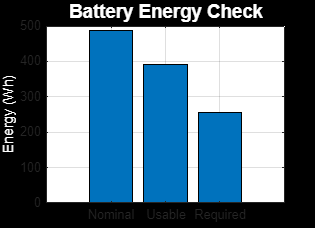

    
%% Plot 2: Battery Energy
figure('Name','Battery Energy', ...
       'Color','k', ...
       'WindowStyle','normal', ...
       'Position',[150 150 900 650]);

ax = axes;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
bar([bat.nominalEnergy_Wh bat.usableEnergy_Wh energy.required_Wh], 'FaceColor','flat');
set(gca,'XTickLabel',{'Nominal','Usable','Required'});
title('Battery Energy Check','Color','w','FontSize',14);
ylabel('Energy (Wh)','Color','w');
grid on

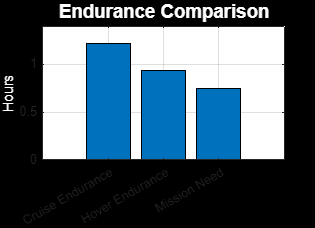


%% Plot 3: Endurance
figure('Name','Endurance Comparison', ...
       'Color','k', ...
       'WindowStyle','normal', ...
       'Position',[200 200 900 650]);

ax = axes;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
bar([perf.cruiseEndurance_hr perf.hoverEndurance_hr mission.required_hr], 'FaceColor','flat');
set(gca,'XTickLabel',{'Cruise Endurance','Hover Endurance','Mission Need'});
title('Endurance Comparison','Color','w','FontSize',14);
ylabel('Hours','Color','w');
grid on

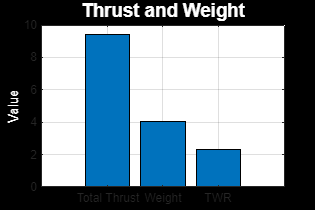


%% Plot 4: Thrust and Weight
figure('Name','Thrust and Weight', ...
       'Color','k', ...
       'WindowStyle','normal', ...
       'Position',[250 250 900 650]);

ax = axes;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
bar([prop.totalThrust_kgf veh.totalMass_kg prop.TWR], 'FaceColor','flat');
set(gca,'XTickLabel',{'Total Thrust','Weight','TWR'});
title('Thrust and Weight','Color','w','FontSize',14);
ylabel('Value','Color','w');
grid on

set(gcf,'Position',[50 50 1200 800]);


%% 12) SIMULINK WORKSPACE EXPORT
vars = {'veh', 'bat', 'prop', 'pwr', 'mission', 'energy', 'current', 'perf', 'feasible', 'results'};
for i = 1:length(vars)
    assignin('base', vars{i}, eval(vars{i}));
end